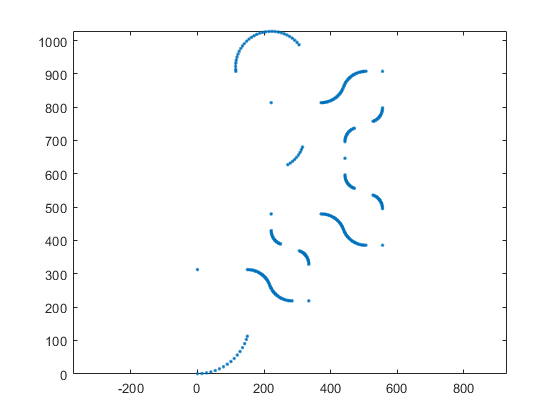

load trayectorianoSuave.mat
% trayectoria1
plot(x,y,'.')
axis('equal')

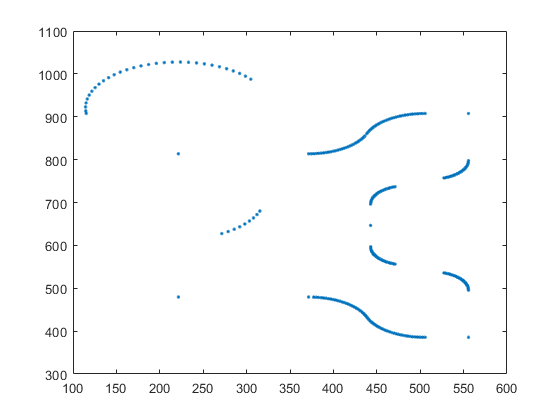


Aux=x<417 & y < 460;

plot(x(~Aux),y(~Aux),'.')

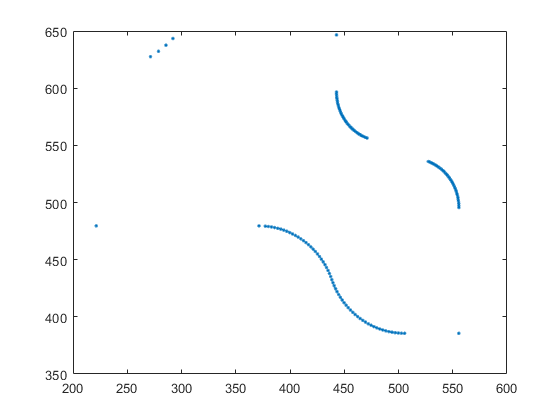

x2=x(~Aux);
y2=y(~Aux);

Aux2=y2> 647;
plot(x2(~Aux2),y2(~Aux2),'.')

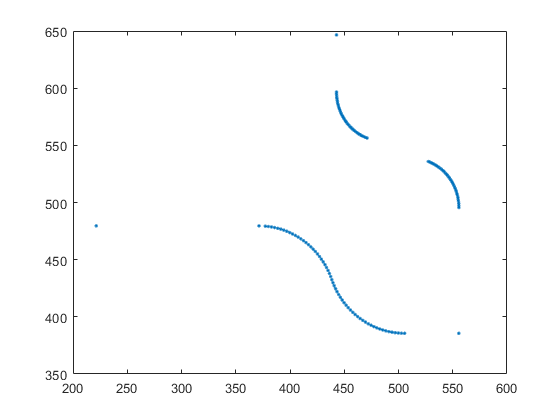


x3=x2(~Aux2);
y3=y2(~Aux2);

Aux3=x3<350 & y3>550;
x4=x3(~Aux3);
y4=y3(~Aux3);
plot(x4,y4,'.')


centro1 = [271.4389,627.5731]

centro1 =   271.4389  627.5731


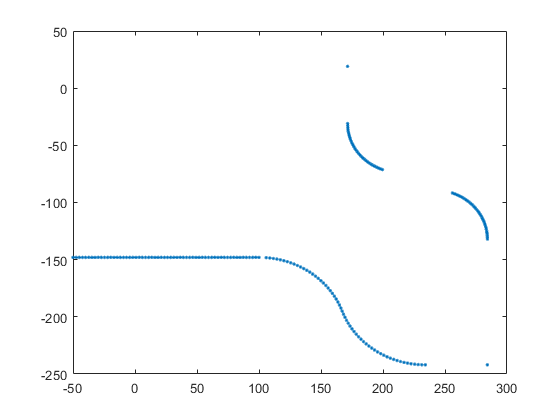


tx1=x4-centro1(1);
ty1=y4-centro1(2);

% como hace la trayectoria alrevez
tx1=tx1(end:-1:1);
ty1=ty1(end:-1:1);
% agregar puntos a linea rectas
% entre indices 1 y 2
Aux9=([tx1(2);ty1(2)]-[tx1(1);ty1(1)])*linspace(0,1,60)+[tx1(1);ty1(1)];

Ntx1=[Aux9(1,:)';tx1(3:end)];
Nty1=[Aux9(2,:)';ty1(3:end)];

plot(Ntx1,Nty1,'.')

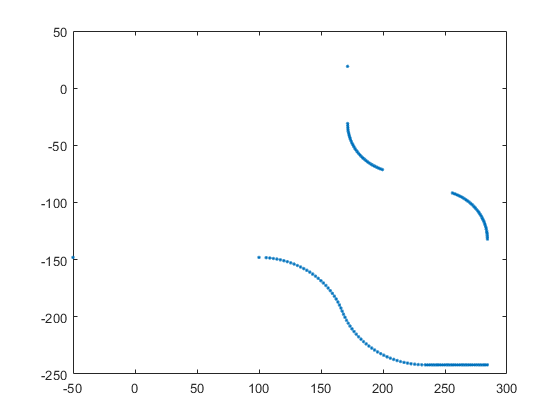


% indices 61 y 62
Aux10=([tx1(62);ty1(62)]-[tx1(61);ty1(61)])*linspace(0,1,30)+[tx1(61);ty1(61)];
N2tx1=[tx1(1:60);Aux10(1,:)';tx1(63:end)];
N2ty1=[ty1(1:60);Aux10(2,:)';ty1(63:end)];
plot(N2tx1,N2ty1,'.')

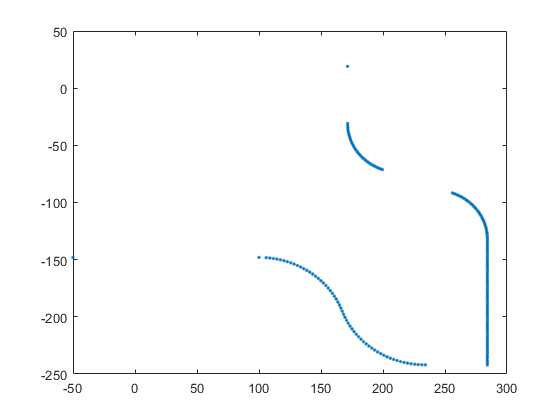


%ndices 62 y 63
Aux11=([tx1(63);ty1(63)]-[tx1(62);ty1(62)])*linspace(0,1,60)+[tx1(62);ty1(62)];
N3tx1=[tx1(1:61);Aux11(1,:)';tx1(64:end)];
N3ty1=[ty1(1:61);Aux11(2,:)';ty1(64:end)];

plot(N3tx1,N3ty1,'.')

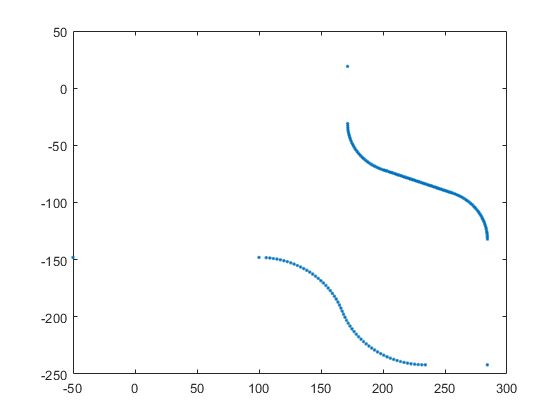

%ndices 93 y 94
Aux12=([tx1(94);ty1(94)]-[tx1(93);ty1(93)])*linspace(0,1,60)+[tx1(93);ty1(93)];
N4tx1=[tx1(1:92);Aux12(1,:)';tx1(95:end)];
N4ty1=[ty1(1:92);Aux12(2,:)';ty1(95:end)];

plot(N4tx1,N4ty1,'.')

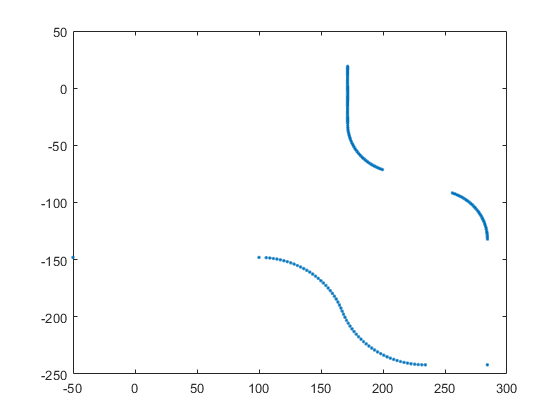

%ndices 124 y 125
Aux13=([tx1(125);ty1(125)]-[tx1(124);ty1(124)])*linspace(0,1,60)+[tx1(124);ty1(124)];
N5tx1=[tx1(1:123);Aux13(1,:)'];
N5ty1=[ty1(1:123);Aux13(2,:)'];
plot(N5tx1,N5ty1,'.')

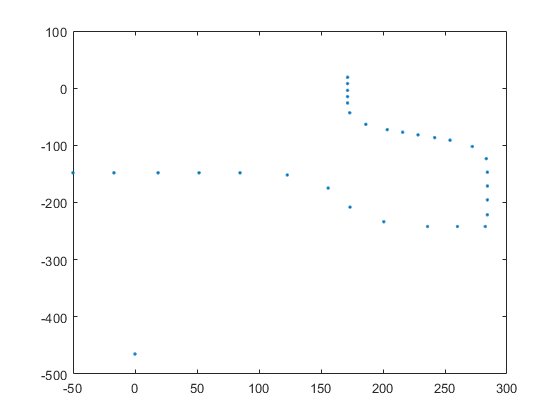


% trayectoria completa
NTx1=[Aux9(1,:)';tx1(3:60);Aux10(1,:)';Aux11(1,:)';tx1(64:92);Aux12(1,:)';tx1(95:123);Aux13(1,:)'];
NTy1=[Aux9(2,:)';ty1(3:60);Aux10(2,:)';Aux11(2,:)';ty1(64:92);Aux12(2,:)';ty1(95:123);Aux13(2,:)'];

x=NTx1(round(linspace(1,length(NTx1),30)));
y=NTy1(round(linspace(1,length(NTy1),30)));

Nx=[0;x;0];
Ny=[-465;y;-465];
% Nx=[x];
% Ny=[y];

plot(Nx,Ny,'.')

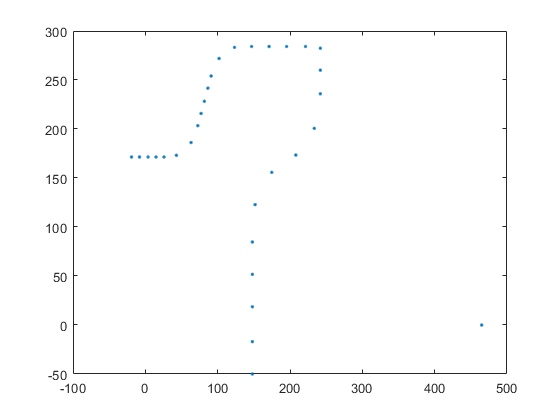


% rotandole

N2x=-Ny;
N2y=Nx;

plot(N2x,N2y,'.')

% trayectoria 2
% plot(x(178+2:304),y(178+2:304),'.')
